## Part 1

### define x,t,m

x = linspace(0,1,200);
t = linspace(0,10,201);
m = 0;

### define ic


$$\mathrm{ic}\;u\left(x,0\right)=2e^x$$


function ic = ic_heat(x)
    ic = 2*exp(x);
end

### define bc


$$u\left(0,t\right)=0$$



$$u\left(2,t\right)=50$$


function [pl,ql,pr,qr] = bc_heat(xl,ul,xr,ur,t)
    pr = ur - 35;
    pl = ul;
    qr = 0;
    ql = 0;
end

### define equation pde


$$\frac{\partial^2 u}{\partial x^2 }-\frac{\;1}{c^2 }\frac{\partial u}{\partial x}=0$$


$\frac{\;1}{c^2 }=50\Rightarrow$c = 50


$$f=\frac{\;\partial u}{\partial x}$$



$$s=0$$


function [c,f,s] = pde_heat(x,t,u,DuDx)
    c = 50;
    f = DuDx;
    s = 0;
end

### define pde

pde = pdepe(m,@pde_heat,@ic_heat,@bc_heat,x,t);

### plot

figure;
surf(pde);

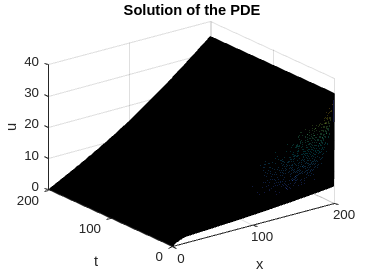

xlabel('x');
ylabel('t');
zlabel('u');
title('Solution of the PDE');